# The damage function with temperature

### Calibration Dietz and Millner

a1 = 2.22 * 10^(-14); 
a2 = 0.75 * 10^(-2);
a3 = 2;

syms T
D = 1/(1 + a1 * (T) + a2 * (T)^a3);
% fplot(D, [0 40])
% title( 'Millner and Dietz calibration')
% xlabel('Temperature', 'BusyAction','queue')
% ylabel('Reduction of the output', 'VerticalAlignment','baseline')

### Calibration AD-DICE

A1 = 0.0012; 
A2 = 0.0023;
A3 = 2.32;

syms T
AD = 1/(1 + A1 * (T) + A2 * (T)^A3);
% fplot(AD, [0 40])
% title( 'AD-DICE calibration')
% xlabel('Temperature', 'BusyAction','queue')
% ylabel('Reduction of the output', 'VerticalAlignment','baseline')


## Comparaison

warning('off')
fplot([AD, D], [0 40])
legend('AD-DICE', 'Millner', 'Location', 'northeast')
title( {'Comparaison des calibrations ','des fonctions de dommages'})
xlabel('Temperature', 'BusyAction','queue')
ylabel('Reduction of the output', 'VerticalAlignment','baseline')
grid on
ylim([0 1])

# Adaptation benefits

### Specification Dietz and Millner

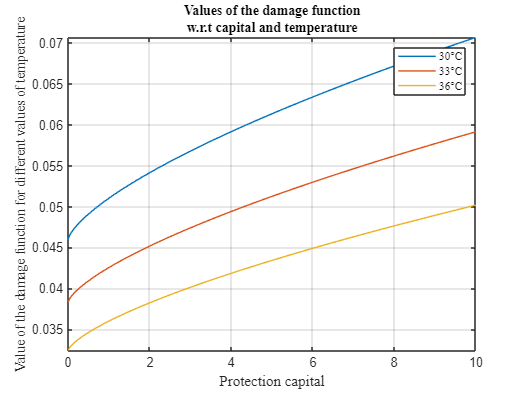

b1 = 0.32 * 10^(-2);
b2 = 0.17;
a1 = 2.22 * 10^(-14); 
a2 = 0.75 * 10^(-2);
a3 = 2;

syms KP T
D = (1 + b1 * (KP)^b2)/(1 + b1 * KP^b2 + a1 *T + a2 * T^a3);

figure;
set(gcf,'color','w');
fplot(subs(D, T, [30, 33, 36]), [0 10])
legend('30°C', '33°C', '36°C', 'Location', 'northeast', 'interpreter', 'latex')
%title({'Values of the damage function', 'w.r.t capital and temperature'}, 'interpreter', 'latex')
xlabel('Protection capital', 'interpreter', 'latex')
ylabel(['Value of the damage function ' ...
    'for different values of temperature'], 'interpreter', 'latex')
grid on

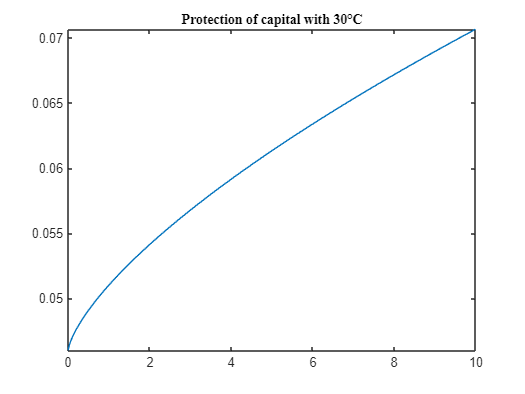

fplot(subs(D, T, 30), [0 10])
title('Protection of capital with 30°C', 'FontName', 'Roman serif')

#### Commentaire:

Il y a deux dimensions à discuter: 

- D'une part, on a, pour une valeur donnée de la température, l'utilité marginale d'investir dans du capital de protection est très faible : il y a globalement une seule valeur approximative qui correspond à chaque valeur de la température, sans forcément beaucoup de décision et de trade-off à prendre quant à la valeur du capital de protection $K_{G,P}$ que l'on souhaite implémenter

- D'autre part, l'utilité globale du capital de protection reste ridiculement faible si l'on en juge par l'investissement que l'on va voir opérer en capital de protection.

### Specification AD-DICE

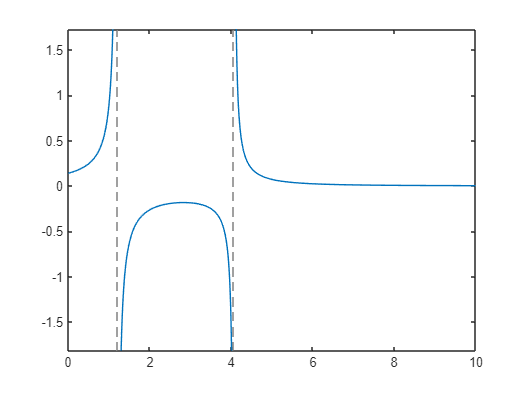

B1 = 0.115;
B2 = 3.6;
A1 = 0.0012; 
A2 = 0.0023;
A3 = 2.32;

syms T KP
AD = 1/( 1 + (1 - KP)*(A1 * T + A2 * T^A3) + B1 * KP^(B2));
invD = 1 + (1 - KP)*(A1 * T + A2 * T^A3) + B1 * KP^(B2);
fplot(subs(AD, T, 30), [0 10])

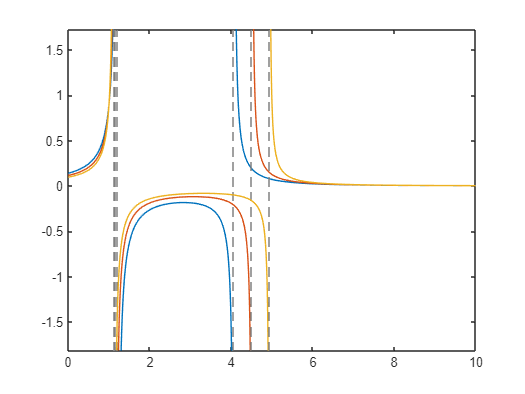


figure;
set(gcf,'color','w');
fplot(subs(AD, T, [30 33 36]), [0 10])
legend('30°C', '33°C', '36°C', 'Location', 'northeast', 'interpreter', 'latex')
%title({'Values of the damage function', 'w.r.t capital and temperature'}, 'interpreter', 'latex')
xlabel('Protection capital', 'interpreter', 'latex')
ylabel(['Value of the damage function ' ...
    'for different values of temperature'], 'interpreter', 'latex')
grid on


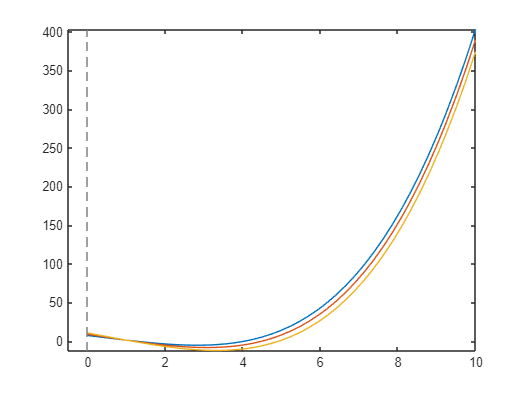


fplot(subs(invD, T, [30 33 36]), [-0.5 10])

#### Commentaire:

Le problème de cette spécification, c'est qu'elle prend des formes trop diverses pour pouvoir obtenir à la fin un modèle RBC équilibré. Ce qui est dommage car, comme la suite le montre, le comportement de cette fonction sur l'intervalle $[0,1]$ pour le capital de protection $K_{G,P}$ est très intéressant. Peut-être vaudra-t-il le coup, alors, d'essayer de l'implémenter en ratio au GDP, pour rester dans cet intervalle ? 

# Adaptation benefits with temperature

### Specification Dietz and Millner

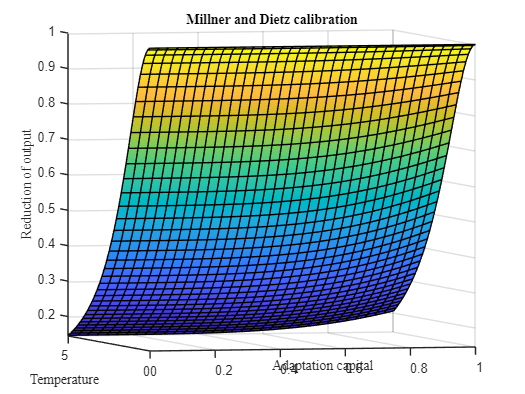

b1 = 0.32 * 10^(-2);
b2 = 0.17;
a1 = 2.22 * 10^(-14); 
a2 = 0.75 * 10^(-2);
a3 = 2;

syms T KP
D(KP,T) = (1 + b1 * (KP)^b2)/(1 + b1 * (KP)^b2 + a1 * (T) + a2 * (T)^a3);

figure;
set(gcf,'color','w');
fsurf( D, [0 1.1 1 5])
%title( 'Millner and Dietz calibration', 'FontName', 'Roman serif')
ylabel('Temperature', 'Interpreter','latex')

xlabel('Adaptation capital', 'Interpreter','latex')
zlabel('Reduction of output', 'Interpreter','latex')
view([-14.122 2.953])
grid on 

B1 = 0.115;
b2 = 3.6;
A1 = 0.0012; 
A2 = 0.0023;
A3 = 2.32;

syms T KP b
AD(KP,T,b) =(1 + b * (KP)^b2)/(1 + b * (KP)^b2 + a1 * (T) + a2 * (T)^a3)  * ((nss)^alfa * (betta * (1 - alfa) / (qss * (1 - betta + betta * deltta)))^(1 - alfa)  * (betta^(12) * (alfaG) / (qIss * (1 - betta + betta * delttaI)))^(alfaG) )^(1 / (alfa - alfaG));

$$T3 = \frac{7234456262383539\,\left({\mathrm{KP}}^{18/5}\,b+1\right)}{562949953421312\,\left({\mathrm{KP}}^{18/5}\,b+\frac{31}{10}\right)}$$

$$T20 = \frac{7234456262383539\,\left({\mathrm{KP}}^{18/5}\,b+1\right)}{562949953421312\,\left({\mathrm{KP}}^{18/5}\,b+\frac{466}{5}\right)}$$

T3 = AD(KP, 3, b)

$$T35 = \frac{7234456262383539\,\left({\mathrm{KP}}^{18/5}\,b+1\right)}{562949953421312\,\left({\mathrm{KP}}^{18/5}\,b+\frac{2831}{10}\right)}$$

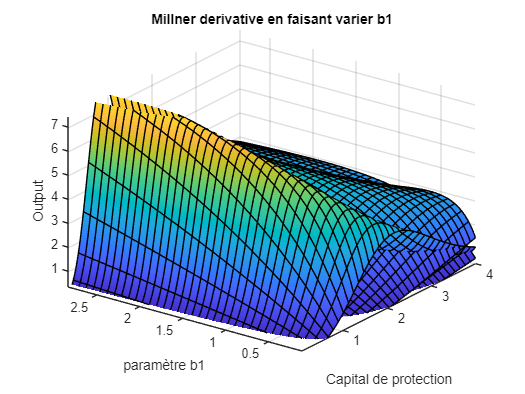

T20 = AD(KP, 20, b)
T35 = AD(KP,35,b)

fsurf([diff(T3, KP) diff(T20, KP) diff(T35, KP)  ], [0.1 4 0 3])
title('Millner derivative en faisant varier b1')
xlabel('Capital de protection')
ylabel('paramètre b1')
zlabel('Output')
ylim([0.11 2.84])

zlim([0.36 7.46])
view([-53.64 32.30])
%legend('Location', 'northeast')

#### Donc il faut avoir un paramètre $b_1$ suffisamment élevé pour que la dérivée ne s'annule pas, et donc pour que l'on puisse avoir un résultat. 

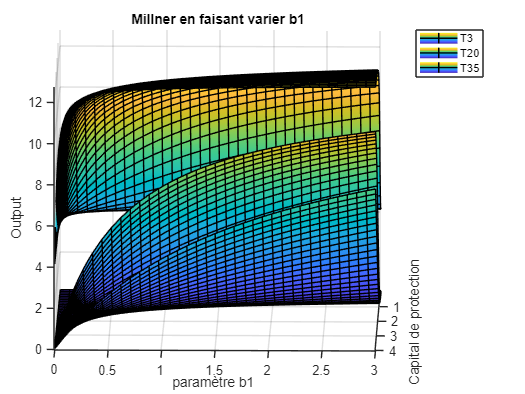


fsurf([T3 T20 T35], [0.1 4 0 3])
title('Millner en faisant varier b1')
xlabel('Capital de protection')
ylabel('paramètre b1')
zlabel('Output')
legend('T3', 'T20', 'T35')
view([-269.02 12.21])

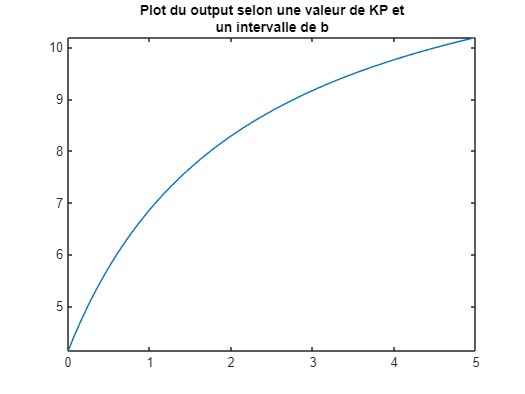

fplot(b, subs(T3, KP, 1.1), [0 5])
title({'Plot du output selon une valeur de KP et' 'un intervalle de b'})

syms T KP b
AD(KP,T,b) =(1 + b1 * (KP)^b2)/(1 + b * (KP)^b2 + a1 * (T) + a2 * (T)^a3) * ((nss)^alfa * (betta * (1 - alfa) / (qss * (1 - betta + betta * deltta)))^(1 - alfa)  * (betta^(12) * (alfaG) / (qIss * (1 - betta + betta * delttaI)))^(alfaG) )^(1 / (alfa - alfaG));
T30 = AD(KP, 3, b);
bb = vpasolve(diff(T30, KP), b)

$$bb = 1.55$$

syms T KP b
AD(KP,T,b) = (1 + b1 * (KP)^b)/(1 + b1 * (KP)^b2 + a1 * (T) + a2 * (T)^a3);
T3 = AD(KP, 3, b)

$$T3 = \frac{\frac{{\mathrm{KP}}^{b}}{2}+1}{\frac{{\mathrm{KP}}^{18/5}}{2}+\frac{31}{10}}$$

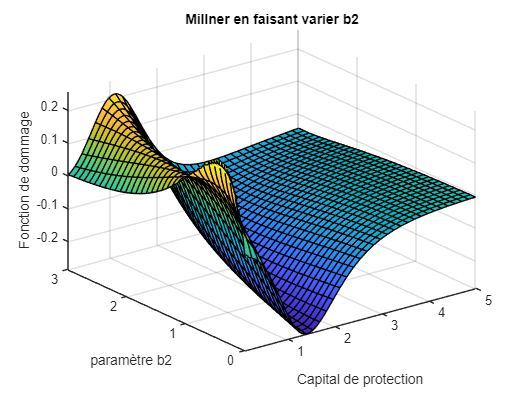

fsurf(diff(T3, KP), [0.1 5 0 3])
title('Millner en faisant varier b2')
xlabel('Capital de protection')
zlabel('Fonction de dommage')
ylabel('paramètre b2')

### Specification AD-DICE

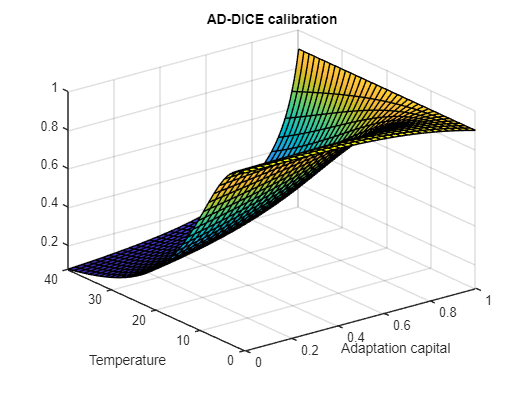

B1 = 0.115;
B2 = 3.6;
A1 = 0.0012; 
A2 = 0.0023;
A3 = 2.32;


syms T KP
AD(KP,T) = (1 + (1 - KP)*(A1 * T + A2 * T^A3) + B1 * KP^(B2))^(-1);


figure;
set(gcf,'color','w');
fsurf(AD, [0 1 0 40])
%legend('30°C', '33°C', '36°C', 'Location', 'northeast', 'interpreter', 'latex')
%title({'Values of the damage function', 'w.r.t capital and temperature'}, 'interpreter', 'latex')
ylabel('Temperature', 'interpreter', 'latex')
xlabel('Adaptation capital', 'interpreter', 'latex')
grid on



title( 'AD-DICE calibration')


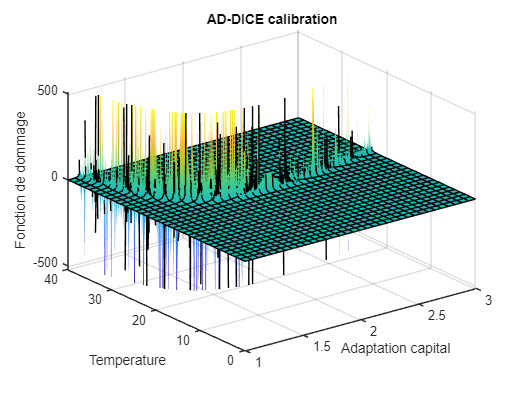




fsurf(AD, [1 3 0 40])
%title( 'AD-DICE calibration')
ylabel('Temperature', 'BusyAction','queue')
xlabel('Adaptation capital', 'VerticalAlignment','baseline')
zlabel('Fonction de dommage')

B1 = 0.115;
B2 = 3.6;
A1 = 0.0012; 
A2 = 0.0023;
A3 = 2.32;

syms T KP b
AD(KP,T,b) = (1 + (1 - KP)*(A1 * T + A2 * T^A3) + b * KP^(B2))^(-1);
T3 = AD(KP, 3, b)

$$T3 = \frac{1}{{\mathrm{KP}}^{18/5}\,b-\left(\frac{207\,3^{8/25}}{10000}+\frac{9}{2500}\right)\,\left(\mathrm{KP}-1\right)+1}$$

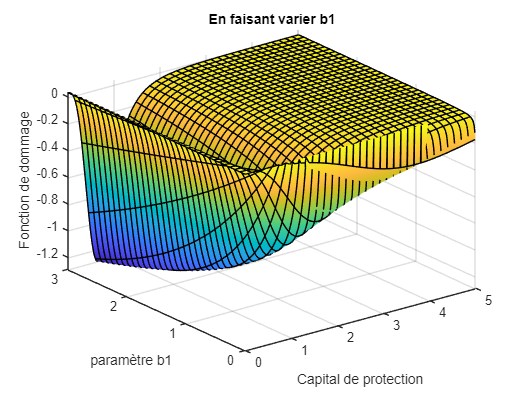

fsurf(diff(T3, KP), [0 5 0 3])
title('En faisant varier b1')
xlabel('Capital de protection')
ylabel('paramètre b1')
zlabel('Fonction de dommage')

syms T KP b
AD(KP,T,b) = (1 + (1 - KP)*(A1 * T + A2 * T^A3) + B1 * KP^(b))^(-1);
T3 = AD(KP, 3, b)

$$T3 = \frac{1}{\frac{23\,{\mathrm{KP}}^{b}}{200}-\left(\frac{207\,3^{8/25}}{10000}+\frac{9}{2500}\right)\,\left(\mathrm{KP}-1\right)+1}$$

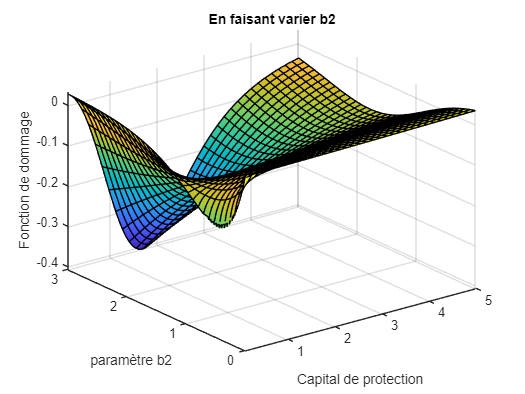

fsurf(diff(T3, KP), [0.1 5 0 3])
title('En faisant varier b2')
xlabel('Capital de protection')
ylabel('paramètre b2')
zlabel('Fonction de dommage')

# The damage function and adaptation benefits with deviation of the temperature with respect to its optimal value 

### Calibration Dietz and Millner

b1 = 0.115;
b2 = 1;  
a1 = 0.0012; 
a2 = 0.0023;
a3 = 2.3;
tempm = 36;
tempopt = 33; 

### Calibration AD-DICE

b1 = 0.115;
b2 = 1;  
a1 = 0.0012; 
a2 = 0.0023;
a3 = 2.3;
tempm = 3;
tempopt = 0; 

syms KP tempm;
D = (1 + b1 * (KP)^b2)/(1 + b1 * (KP)^b2 + a1 * (tempm) + a2 * (tempm)^a3);

fplot(subs(D, tempm, [3, 6, 9]), [0 10])
legend show


alfaG = 0.1;
alfa = 0.4;
betta = 0.97;
deltta = 0.06;
delttaI = 0.02;
delttaP = 0.06;
sigmaC = 1.5;
sigmaN = .5;
rhot = 0.95;
sigma = 2;

qss = 1; 
qPss = 1;
qIss = 1;
tempss = tempm;
nss = 1/3;

N = 1;

b1 = 0.32 * 10^(-2);
b2 = 0.17;
a1 = 2.22 * 10^(-14); 
a2 = 0.75 * 10^(-2);
a3 = 2;




syms PIB KP; % il faut réécrire les code matlab ici (plutôt que les tâches) et remplacer tau par la différence
assume(PIB > 0 & KP > 0);
PIB(KP) = ((1 + b1 * (KP)^b2)/(1 + b1 * (KP)^b2 + a1 * (tempss - tempopt) + a2 * (tempss - tempopt)^2) *  (nss)^alfa * (betta * (1 - alfa) / (qss * (1 - betta + betta * deltta)))^(1 - alfa) )^(1 / (alfa))  - KP * qPss * (1 - betta *(1 - delttaP))/betta^N;
Yd = diff(PIB, KP);
kPss = vpasolve(Yd, KP);
PIB(KP) = ((1 + b1 * (KP)^b2)/(1 + b1 * (KP)^b2 + a1 * (tempss - tempopt) + a2 * (tempss - tempopt)^2) *  (nss)^alfa * (betta * (1 - alfa) / (qss * (1 - betta + betta * deltta)))^(1 - alfa) )^(1 / (alfa));
Yss = PIB(kPss);